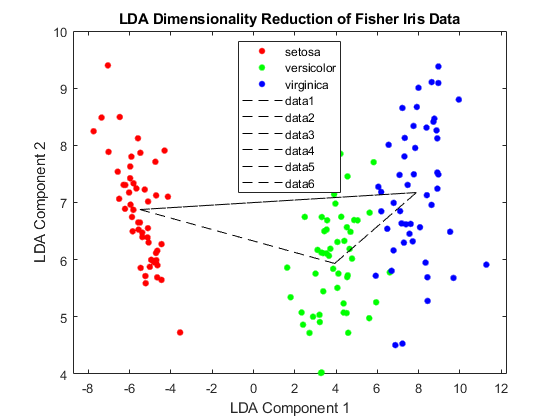

% Step 1: Load the fisheriris dataset
clc
clear
load fisheriris.mat

% Step 2: Extract the feature matrix X and class labels y
X = meas; % Feature matrix (150 samples x 4 features)
y = species; % Class labels (setosa, versicolor, virginica)

% Step 3: Apply LDA for dimensionality reduction
num_components = 2; % Number of components in the reduced space
lda_model = fitcdiscr(X, y); % Fit the LDA model
[eigenvectors, eigenvalues] = eig(lda_model.BetweenSigma, lda_model.Sigma);
[~, sorted_indices] = sort(diag(eigenvalues), 'descend');
projection_matrix = eigenvectors(:, sorted_indices(1:num_components));

% Step 4: Project data onto the LDA components
X_reduced = X * projection_matrix;

% Step 5: Visualization in the reduced dimensional space
gscatter(X_reduced(:, 1), X_reduced(:, 2), y, 'rgb');
title('LDA Dimensionality Reduction of Fisher Iris Data');
xlabel('LDA Component 1');
ylabel('LDA Component 2');
legend('setosa', 'versicolor', 'virginica', 'Location', 'best');

% Step 6: Generate predictor lines between each class
class_means = lda_model.Mu;
for i = 1:size(class_means, 1)
    start_point = class_means(i, :) * projection_matrix;
    for j = 1:size(class_means, 1)
        if i ~= j
            end_point = class_means(j, :) * projection_matrix;
            line([start_point(1), end_point(1)], [start_point(2), end_point(2)], 'LineStyle', '--', 'Color', 'k');
        end
    end
end